
$${\mathbf{y}}^{\prime } =\left\lbrack \begin{array}{c}
3\;y_1 -3t^2 y_2 \\
3{t\cdot y}_1 -y_2 
\end{array}\right\rbrack ;\mathbf{y}\left(0\right)=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ;t=\left\lbrack 0,10\right\rbrack ;h=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 1\right)$$



$$D_y \mathbf{f}=\left\lbrack \begin{array}{cc}
3 & -3t^2 \\
3t & -1
\end{array}\right\rbrack$$



$$\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)=\left\lbrack \begin{array}{c}
3\;y_1^{\left(i+1\right)} -3{t_{i+1} }^2 y_2^{\left(i+1\right)} \\
3{t_{i+1} \cdot y}_1^{\left(i+1\right)} -y_2^{\left(i+1\right)} 
\end{array}\right\rbrack \;$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(d\ldotp 1\right)\;\;\;$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=$$

$$h\left\lbrack \begin{array}{c}
3\;\left(y_1^{\left(i\right)} +z_1 \right)-3{t_{i+1} }^2 \left(y_2^{\left(i\right)} +z_2 \right)\\
3t_{i+1} \left(y_1^{\left(i\right)} +z_1 \right)-\left(y_2^{\left(i\right)} +z_2 \right)
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack$$


(i = 0)


$${\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=$$

$$h\left\lbrack \begin{array}{c}
3\;\left(y_1^{\left(0\right)} +z_1 \right)-3{t_1 }^2 \left(y_2^{\left(0\right)} +z_2 \right)\\
3t_1 \left(y_1^{\left(0\right)} +z_1 \right)-\left(y_2^{\left(0\right)} +z_2 \right)
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=$$

$$\left\lbrack \begin{array}{c}
3\;\left(0+z_1 \right)-3\left(1+z_2 \right)-z_1 \\
3\left(0+z_1 \right)-\left(1+z_2 \right)-z_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2z_1 -3z_2 -3\\
3z_1 -2z_2 -1
\end{array}\right\rbrack$$



$${DF}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
2 & -3\\
3 & -2
\end{array}\right\rbrack$$


syms z2 z1;
ti = 0;
h = 1;
yi=[0;1]

yi =      0
     1


tspan = [0,10]

tspan =      0    10


n = 10;
tol = 10^(-8);
nmax = 100;
f = @(t,y) [3*y(1)-3*t^2*y(2);3*t*y(1)-y(2)];
df = @(t,z) [3,-3*t^2;3*t,-1];
[F_e,F_J] = F_euler([z1;z2],ti,h,yi,f,df) 

$$F\_e = \left(\begin{array}{c} 2\,z_{1}-3\,z_{2}-3\\ 3\,z_{1}-2\,z_{2}-1 \end{array}\right)$$

F_J =      2    -3
     3    -2


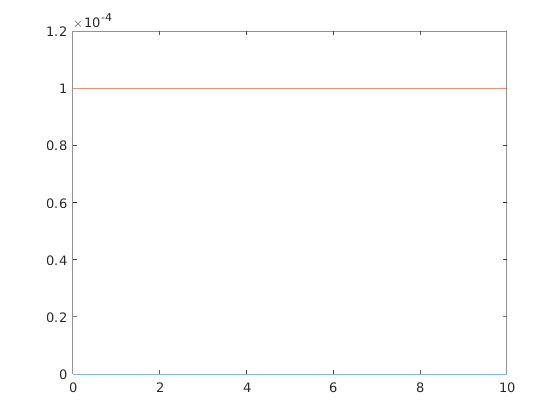

[t,y_euler] = impl_euler(f,tspan,yi,n,df,tol,nmax);
y_euler = y_euler * 10^(-4);
plot(t,y_euler)

y0 = [0;1]

y0 =      0
     1


[t,y_ode] = ode45(f,tspan,y0)

t =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.2658
    0.3306
    0.3955
    0.4603
    0.5315


y_ode = 	1.0e+04 *

         0    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001


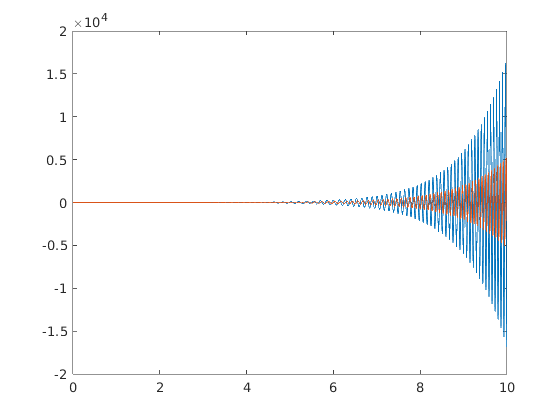

plot(t,y_ode)


[z_n,fval,exitflag]=newton(@f_beispiel,[0;0],tol,nmax)

z_n =    -1.5000
   -2.0000


fval = 	1.0e+-8 *

    0.0000
    0.3713


exitflag = 1

y1 = y0 + z_n

y1 =    -1.5000
   -1.0000



$${\Rightarrow \;\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
\left(\left(2+z_1 \right)-3\left(1+z_2 \right)\right)-z_1 \\
\left(3\left(2+z_1 \right)-\left(1+z_2 \right)\right)-z_2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(d\ldotp 5\right)$$



$${\Rightarrow \;\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
-3z_2 -1\\
3z_1 -2z_2 +5
\end{array}\right\rbrack$$



$${\Rightarrow D\;\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
0 & -3\\
3 & -2
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(d\ldotp 6\right)$$


syms z2 z1;
ti = 0;
h = 1;
yi=[2;1]

yi =      2
     1


f = @(t,z) [-3*z(2)-1;3*z(1)-2*z(2)+5];
df = @(t,z) [0,-3;3,-2];
jacobian([-3*z2-1;3*z1-2*z2+5],[z1;z2])

$$ans = \left(\begin{array}{cc} 0 & -3\\ 3 & -2 \end{array}\right)$$

[F_e,F_J] = F_euler([z1;z2],ti,h,yi,f,df) 

$$F\_e = \left(\begin{array}{c} -z_{1}-3\,z_{2}-4\\ 3\,z_{1}-3\,z_{2}+9 \end{array}\right)$$

F_J =     -1    -3
     3    -3


F_e + [3;-4]

$\mathbf{y}=\left\lbrack \begin{array}{c}
3y_2 \\
{-y}_1 
\end{array}\right\rbrack$y(0) = [1;1]


$$\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)=\left\lbrack \begin{array}{c}
{{3y}^{\left(i+1\right)} }_2 \\
{-y^{\left(i+1\right)} }_1 
\end{array}\right\rbrack$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$



$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
{{3y}_2 }^{\left(i\right)} +3z_2 -z_1 \\
-{y^{\left(i\right)} }_1 +z_1 -z_2 
\end{array}\right\rbrack$$


(i=0)


$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{c}
3+{3z}_2 -z_1 \\
-1+z_1 -z_2 
\end{array}\right\rbrack$$



$${\Rightarrow D\;\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
-1 & +3\\
1 & -1
\end{array}\right\rbrack$$


syms z2 z1;
ti = 0;
h = 1;
yi=[1;1]
f = @(t,z) [2+2*z(2)-z(1);-1+z(1)-z(2)];
df = @(t,z) [1,-2;1,-1];
[F_e,F_J] = F_euler([z1;z2],ti,h,yi,f,df) 


$$ans = \left(\begin{array}{c} -z_{1}-3\,z_{2}-1\\ 3\,z_{1}-3\,z_{2}+5 \end{array}\right)$$

yi =      1
     1


$$F\_e = \left(\begin{array}{c} 2\,z_{2}-2\,z_{1}+3\\ z_{1}-2\,z_{2}-1 \end{array}\right)$$

F_J =      0    -2
     1    -2



$${\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=$$

$$\left\lbrack \begin{array}{c}
3\;\left(0+z_1 \right)-3\left(1+z_2 \right)-z_1 \\
3\left(0+z_1 \right)-\left(1+z_2 \right)-z_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2z_1 -3z_2 -3\\
3z_1 -2z_2 -1
\end{array}\right\rbrack$$



$${DF}_{\mathrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
2 & -3\\
3 & -2
\end{array}\right\rbrack$$


function [f,df] = f_beispiel(z)
    f = [2*z(1)-3*z(2)-3;2*z(1)-2*z(2)-1];
    df = [2,-3;3,-2];
end